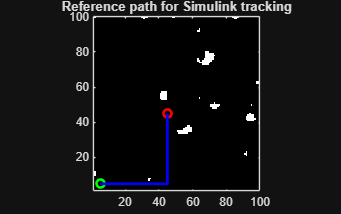

clc; clear; close all;

%% Map generation
mapSize = 100;
map = zeros(mapSize);

blob = imgaussfilt(rand(mapSize), 2) > 0.6;
map(blob) = 1;

start = [5, 5];
goal  = [45, 45];

map(start(1), start(2)) = 0;
map(goal(1), goal(2)) = 0;

%% A* path planning
path = astar(map, start, goal);

if isempty(path)
    error('No path found. Change map or threshold.');
end

%% Optional path smoothing
pp = 1:size(path,1);
ppFine = linspace(1, size(path,1), 5 * size(path,1));
xSmooth = interp1(pp, path(:,1), ppFine, 'pchip');
ySmooth = interp1(pp, path(:,2), ppFine, 'pchip');
path = [xSmooth(:), ySmooth(:)];

%% Vehicle/controller parameters
x0 = path(1,1);
y0 = path(1,2);
theta0 = atan2(path(2,2)-path(1,2), path(2,1)-path(1,1));

L = 2.5;  % wheelbase
vRef = 1.5; % desired speed
Ld = 6;   % look-ahead distance
maxSteer = deg2rad(30);

%% Visual check
figure;
imagesc(map');
colormap(gray);
axis equal;
hold on;
set(gca,'YDir','normal');
xlim([1 mapSize]);
ylim([1 mapSize]);

plot(start(1), start(2), 'go', 'LineWidth', 2);
plot(goal(1), goal(2), 'ro', 'LineWidth', 2);
plot(path(:,1), path(:,2), 'b-', 'LineWidth', 2);
title('Reference path for Simulink tracking');